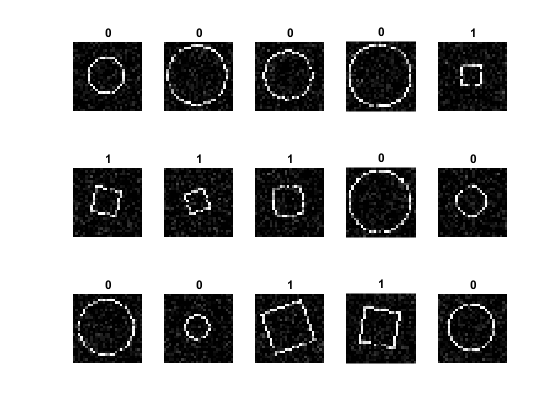

clearvars; clc; close all;
tic
%% Load images and labels
ImagePath= './Images/';
load('./Images/Labels.mat');
imds = imageDatastore(ImagePath,'labels',categorical(Labels));

numImage = length(imds.Files);
ImageSize = size(readimage(imds,1));      % readimage(): Read specified image from datastore
numLabels = size(countEachLabel(imds),1); % countEachLabel(): Count files in ImageDatastore labels

% Show images
figure(1)
random = randperm(numImage,15);
for i = 1:15
    subplot(3,5,i);
    imshow(imread(imds.Files{random(i)}));
    title(Labels(random(i)))      % 0 indicates circle; 1 indicates square
end

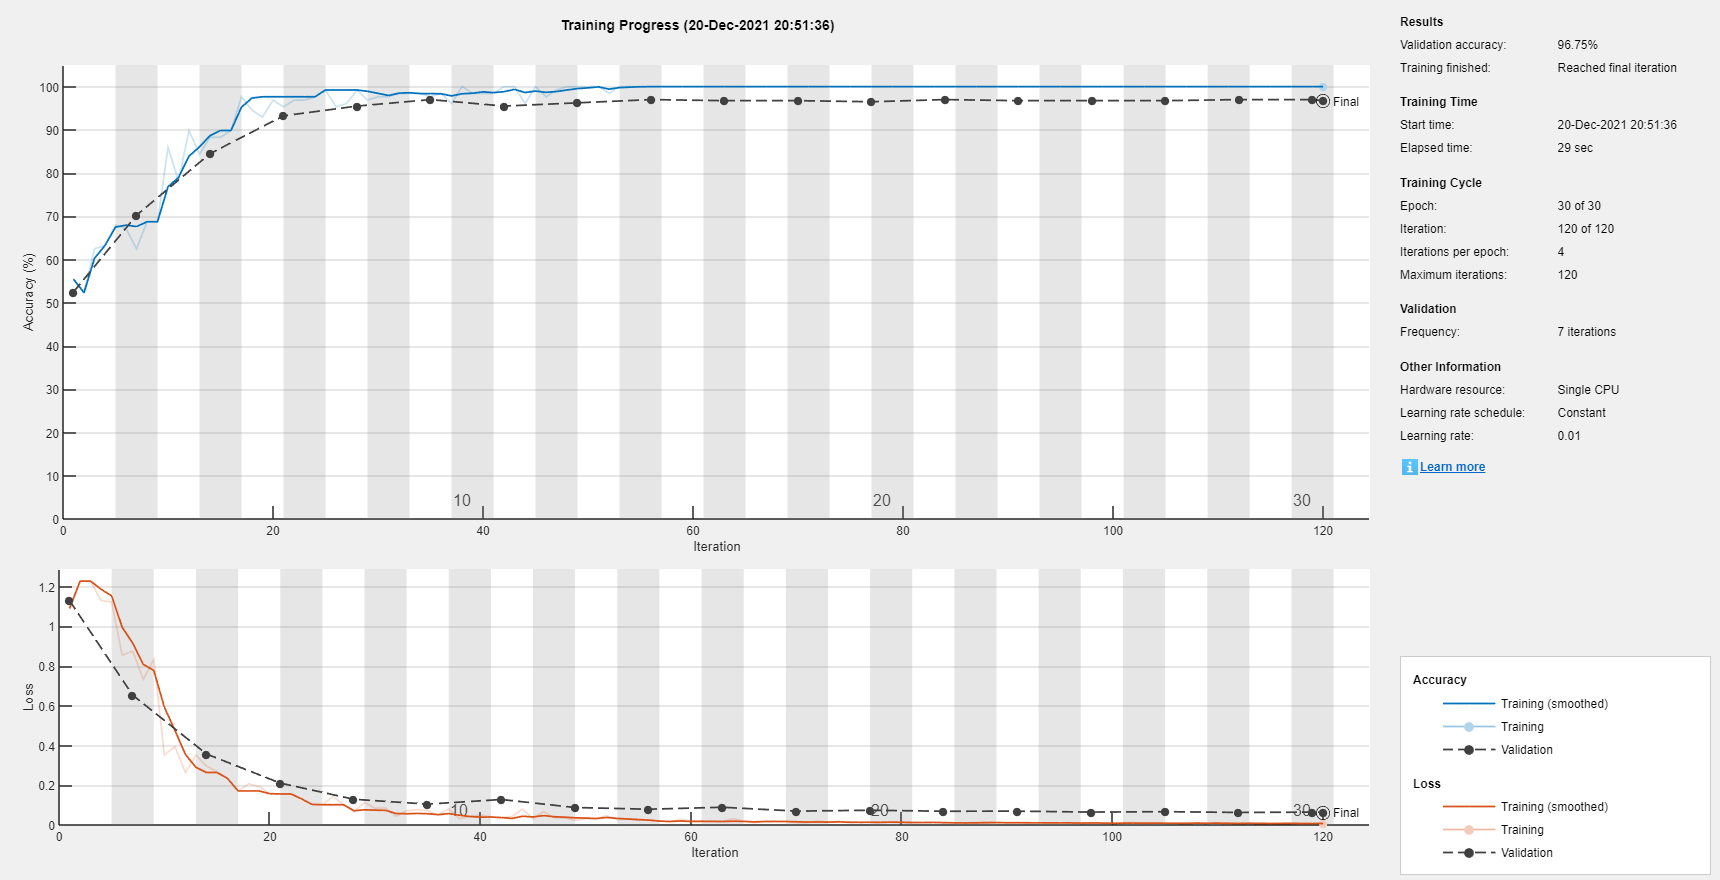


%% Split the data set into a training set and a validation set
TrainFiles = 0.6;    % the percentage of the files to assign to imds_train
[imdsTrain,imdsTest] = splitEachLabel(imds,TrainFiles,'randomized');

%% Define the network architecture
FilterSize = 3;     % Height and width of the filters
numFilters = 9;     % the number of channels in the output of a convolutional layer.

layers = [ ...
    imageInputLayer(ImageSize)
    convolution2dLayer(FilterSize, numFilters, 'Padding', 'same') 
    batchNormalizationLayer
    reluLayer
    %new layer
%     maxPooling2dLayer(2,'Stride',2)
%     convolution2dLayer(3,18,'Padding','same')
%     batchNormalizationLayer
%     reluLayer
    %new layer
    maxPooling2dLayer(2,'Stride',2)
    fullyConnectedLayer(numLabels)
    softmaxLayer
    classificationLayer];

%% Specify the training option
% An epoch is the full pass of the training algorithm over the entire training set.
%epoch will cost resource and time
%InitialLearnRate will help improve learning resource and accuracy with
%this case

options = trainingOptions('sgdm', ...
    'InitialLearnRate', 0.01,  ...    
    'MaxEpochs',30, ...               
    'Shuffle','every-epoch',...
    'ValidationData',imdsTest, ...
    'ValidationFrequency',7, ...      
    'Verbose',false, ...
    'Plots','training-progress');

%% Train the network
net = trainNetwork(imdsTrain,layers,options);


%% Run the trained network on the test set
YClass = classify(net,imdsTest);
YTest = imdsTest.Labels;

%% Calculate the accuracy
%  Accuracy is the fraction of labels that the network predicts correctly
accuracy = sum(YClass == YTest)/numel(YTest)

accuracy = 0.9675

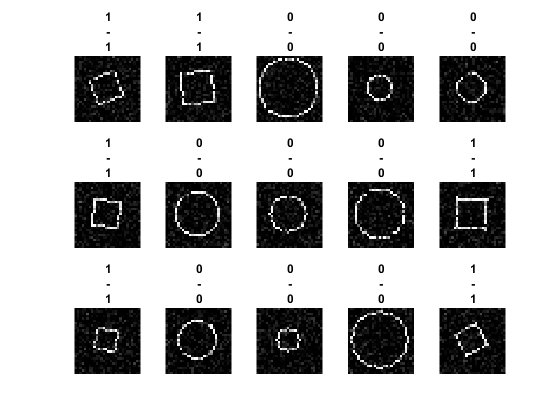


%% Show results
figure(2)
random = randperm(round(numImage*(1-TrainFiles)-1), 15);
for i = 1:15
    R = random(i);
    subplot(3,5,i);
    imshow(imread(imdsTest.Files{R}));
    
    TestResult = YClass(R); 
    Original = imdsTest.Labels(R);
    
    if  TestResult == Original
        title([TestResult,'-',Original]);
    else
        title([TestResult,'-',Original],'color','red');
    end
end

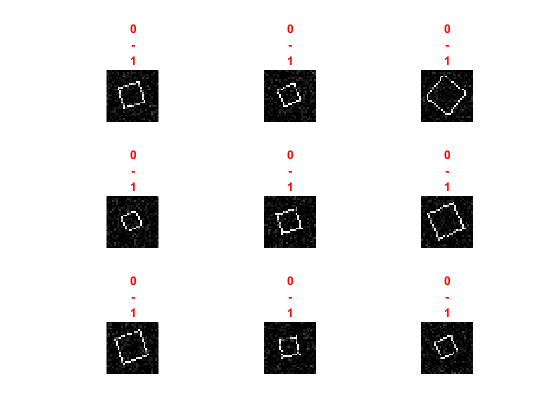


%% Show all wrong results
j = 0; k = [];
for i = 1:200
    if YClass(i) ~= imdsTest.Labels(i)
        j = j+1;
        k(j) = i;
    end
end

figure(3)
for ii = 1:length(k)
    subplot(ceil(length(k)/3),3,ii);
    imshow(imread(imdsTest.Files{k(ii)}))
    title([YClass(k(ii)),'-',imdsTest.Labels(k(ii))],'color','red');
end

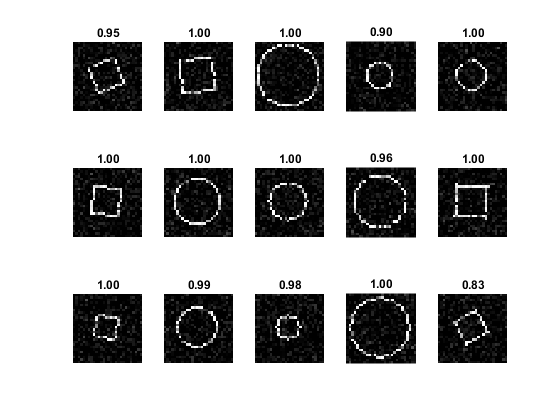

 %% Softmax Layer
 YPredict = predict(net, imdsTest);
 
 %figure('units','normalized','outerposition',[0 0 1/2 1]);
 figure(4)
 for i = 1:15
     R = random(i);
     subplot(3,5,i);
     imshow(imread(imdsTest.Files{R}));
     if YClass(R) == imdsTest.Labels(R)
         title(num2str(max(YPredict(R,:)),'%0.2f'));
     else
         title(num2str(max(YPredict(R,:)),'%0.2f'),'color','red');
     end
 end

 

 toc

Elapsed time is 37.425851 seconds.


% 
% df1=imread(imds.Files(795));
% edf1=edge(df1,'canny_old');
% 
% figure
% 
% [H,T,R]=hough(im2bw(df1));
% imshow(H,[],'XData',T,'YData',R,...
%             'InitialMagnification','fit');
% xlabel('\theta'), ylabel('\rho');
% axis on, axis normal, hold on;
% title('Hough peaks')
% % Find peaks 
% 
% P  = houghpeaks(H,5,'threshold',ceil(0.3*max(H(:))));
% x = T(P(:,2)); y = R(P(:,1));
% plot(x,y,'s','color','white');
% 
% 
% 
% lines = houghlines(edf1,T,R,P,'FillGap',70,'MinLength',3);
% figure,imshow(df1), hold on
% % 
% % imshow(df1)
% max_len = 0;
% for k = 1:length(lines)
%    xy = [lines(k).point1; lines(k).point2];
%    plot(xy(:,1),xy(:,2),'LineWidth',2,'Color','green');
% 
%    % Plot beginnings and ends of lines
%    plot(xy(1,1),xy(1,2),'x','LineWidth',2,'Color','yellow');
%    plot(xy(2,1),xy(2,2),'x','LineWidth',2,'Color','red');
% 
%    % Determine the endpoints of the longest line segment
%    len = norm(lines(k).point1 - lines(k).point2);
%    if ( len > max_len)
%       max_len = len;
%       xy_long = xy;
%    end
% end
% 
% 
% % figure(img+6)
% plot(xy_long(:,1),xy_long(:,2),'LineWidth',2,'Color','#FF00FF');
% hold on
% title('Overlapping line and derive longest L')
% 
% fprintf('Longest length');
% disp(len)